clear
clc
close all

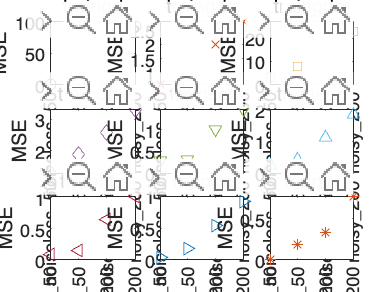

state1 = noiseless_50_mse_values_mean;
state2 = noisy_50_mse_values_mean;
state3 = noiseless_200_mse_values_mean;
state4 = noisy_200_mse_values_mean;

% Define markers and colors for each object
line_styles = {'-', '--', ':', '-.', '-', '--', ':', '-.', '--'};
markers = {'o', 'x', 's', 'd', 'v', '^', '<', '>', '*'};
colors = lines(9); % Generate a set of distinct colors
algorithms = {'traingd', 'traingda', 'traingdm', 'traingdx', 'traincgf', 'traincgp', 'trainbfg', 'trainlm','trainbr'};
x_axis = {'noiseless\_50', 'noisy\_50','noiseless\_200', 'noisy\_200'};

% Create a figure and divide it into a 3x3 grid of subplots
figure;
for i = 1:9
    subplot(3, 3, i);
    
    % Plot the object in each state with unique marker and color
    for state = 1:4
        eval(['data = state', num2str(state), ';']);
        plot(state, data(i), 'LineStyle', line_styles{i},'Marker', markers{i}, 'Color', colors(i, :),'DisplayName', algorithms{i});
        hold on;
    end
    
    % Customize subplot appearance
    title(algorithms(i));
    ylabel('MSE');
    set(gca, 'XTick', 1:4, 'XTickLabel', x_axis);
end


neurons = [20, 40, 60, 80, 100];
layers = [1, 2, 3, 4, 5];

% Sample data (5x5 matrix)
data = val_errors;

函数或变量 'val_errors' 无法识别。


% Create coordinate grid
[X, Y] = meshgrid(layers, neurons);

% Create a figure and plot the data as a surface
figure;
surf(X, Y, data);

% Customize the plot
title('Neurons vs Layers');
xlabel('Layers');
ylabel('Neurons');
zlabel('Data');

% Rotate the plot for better visualization (optional)
view(45, 30);









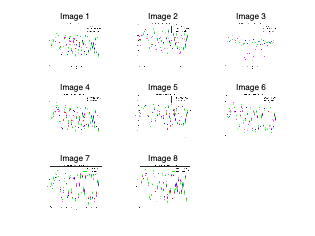

% Load the eight images
img1 = imread('1.png');
img2 = imread('2.png');
img3 = imread('3.png');
img4 = imread('4.png');
img5 = imread('5.png');
img6 = imread('6.png');
img7 = imread('7.png');
img8 = imread('8.png');

% Create a new figure
figure;

% Arrange the images in a 3x3 grid layout
subplot(3, 3, 1);
imshow(img1);
title('Image 1');

subplot(3, 3, 2);
imshow(img2);
title('Image 2');

subplot(3, 3, 3);
imshow(img3);
title('Image 3');

subplot(3, 3, 4);
imshow(img4);
title('Image 4');

subplot(3, 3, 5);
imshow(img5);
title('Image 5');

subplot(3, 3, 6);
imshow(img6);
title('Image 6');

subplot(3, 3, 7);
imshow(img7);
title('Image 7');

subplot(3, 3, 8);
imshow(img8);
title('Image 8');

% Remove the empty subplot
subplot(3, 3, 9);
axis off;

% Adjust the spacing between subplots
spacing = 0.01; % Modify as desired
ax = gca;
ax.Position = ax.OuterPosition - spacing;

% Adjust the figure size if needed
figure_width = 800; % Modify as desired
figure_height = 600; % Modify as desired
set(gcf, 'Position', [100, 100, figure_width, figure_height]);

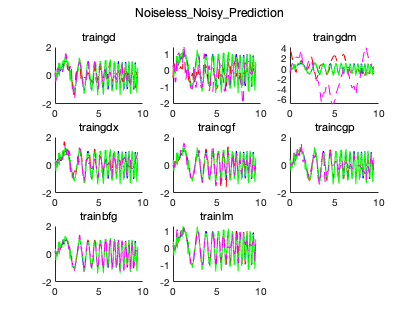

% Open the individual .fig files
fig1 = openfig('1_gd.fig');
fig2 = openfig('2_gda.fig');
fig3 = openfig('3_gdm.fig');
fig4 = openfig('4_gdx.fig');
fig5 = openfig('5_cgf.fig');
fig6 = openfig('6_cgp.fig');
fig7 = openfig('7_bfg.fig');
fig8 = openfig('8_nlm.fig');

% Create the big plot figure
bigFigure = figure;

% Divide the big figure into a 3x3 grid
subplot(3, 3, 1);
title('traingd');
subplot(3, 3, 2);
title('traingda');
subplot(3, 3, 3);
title('traingdm');
subplot(3, 3, 4);
title('traingdx');
subplot(3, 3, 5);
title('traincgf');
subplot(3, 3, 6);
title('traincgp');
subplot(3, 3, 7);
title('trainbfg');
subplot(3, 3, 8);
title('trainlm');


% Copy the individual plots to the corresponding axes in the big figure
copyobj(allchild(get(fig1, 'CurrentAxes')), subplot(3, 3, 1));
copyobj(allchild(get(fig2, 'CurrentAxes')), subplot(3, 3, 2));
copyobj(allchild(get(fig3, 'CurrentAxes')), subplot(3, 3, 3));
copyobj(allchild(get(fig4, 'CurrentAxes')), subplot(3, 3, 4));
copyobj(allchild(get(fig5, 'CurrentAxes')), subplot(3, 3, 5));
copyobj(allchild(get(fig6, 'CurrentAxes')), subplot(3, 3, 6));
copyobj(allchild(get(fig7, 'CurrentAxes')), subplot(3, 3, 7));
copyobj(allchild(get(fig8, 'CurrentAxes')), subplot(3, 3, 8));

% Close the individual figures
close(fig1);
close(fig2);
close(fig3);
close(fig4);
close(fig5);
close(fig6);
close(fig7);
close(fig8);

sgtitle('Noiseless\_Noisy\_Prediction');


% % Optional: Adjust the layout, titles, labels, etc. of the big figure
% 
% % Save the big figure as a .fig file
% savefig('big_plot.fig');
